# **Candidate Networks**

Below are other candidate networks that were tested/considered for this demo.

#### Self-Attention LSTM Network

nFeatures = 3;
layers = [
    sequenceInputLayer(nFeatures)
    selfAttentionLayer(8,256)
    lstmLayer(128, 'OutputMode', 'last')
    fullyConnectedLayer(nFeatures)
    regressionLayer];

#### 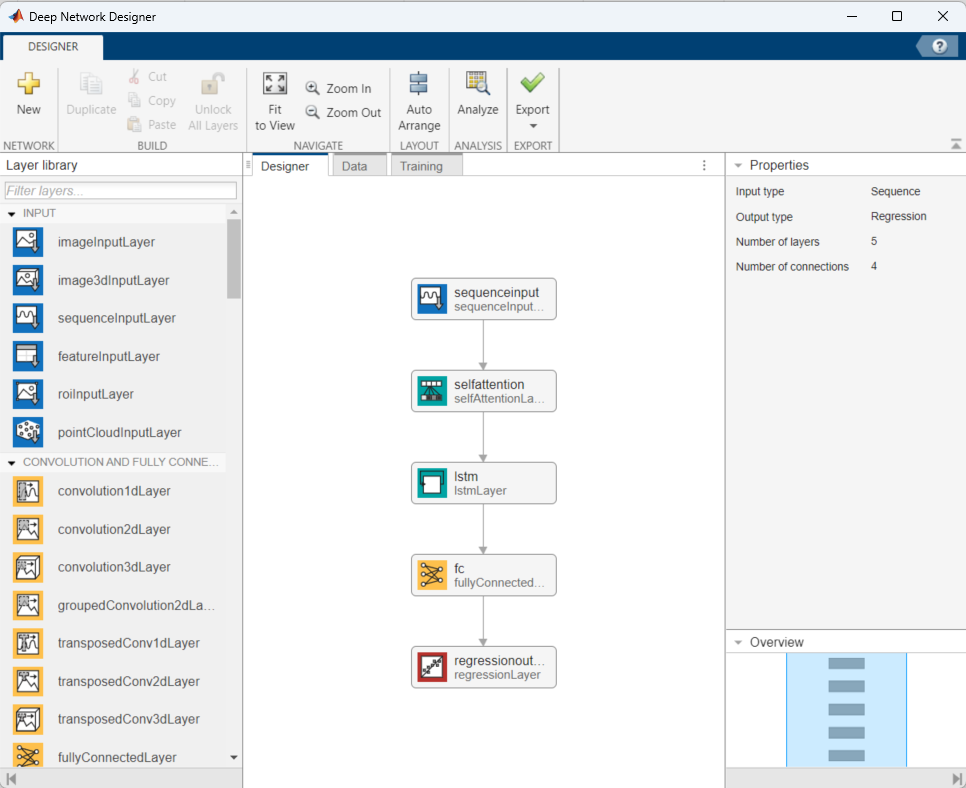

#### Embedding Self-Attention 1D Network

numChannels = 3;
embeddingOutputSize = 64;
numHeads = 4;
numKeyChannels = 4*embeddingOutputSize;

layers = [ 
    sequenceInputLayer(numChannels,Name="input")
    positionEmbeddingLayer(numChannels,128,Name="pos-emb");
    additionLayer(2, Name="add")
    selfAttentionLayer(numHeads,numKeyChannels,AttentionMask="causal")
    indexing1dLayer("last")
    fullyConnectedLayer(numChannels)
    regressionLayer];

lgraph = layerGraph(layers);
lgraph = connectLayers(lgraph,"input","add/in2");

#### 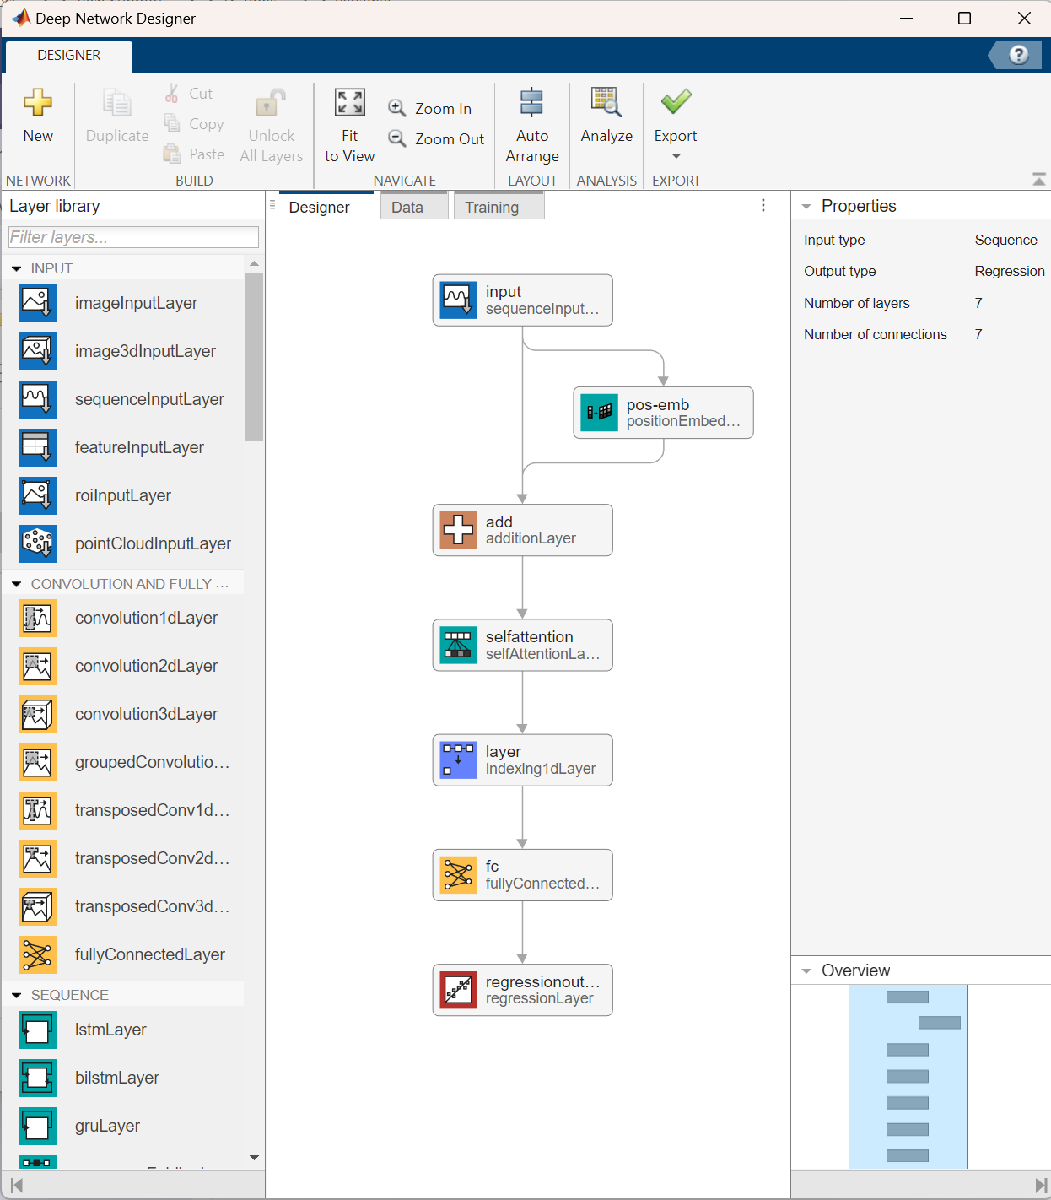

#### Embedding Self-Attention LSTM Network

numChannels = 3;
maxPosition = 64;
numHeads = 3;
numKeyChannels = numHeads*32;
numHiddenUnits = 64;

layers = [ 
    sequenceInputLayer(numChannels,Name="input")
    positionEmbeddingLayer(numChannels,maxPosition,Name="pos-emb");
    additionLayer(2, Name="add")
    selfAttentionLayer(numHeads,numKeyChannels)
    lstmLayer(numHiddenUnits, 'OutputMode', 'last')
    fullyConnectedLayer(numChannels)
    regressionLayer];

lgraph = layerGraph(layers);
lgraph = connectLayers(lgraph,"input","add/in2");

#### 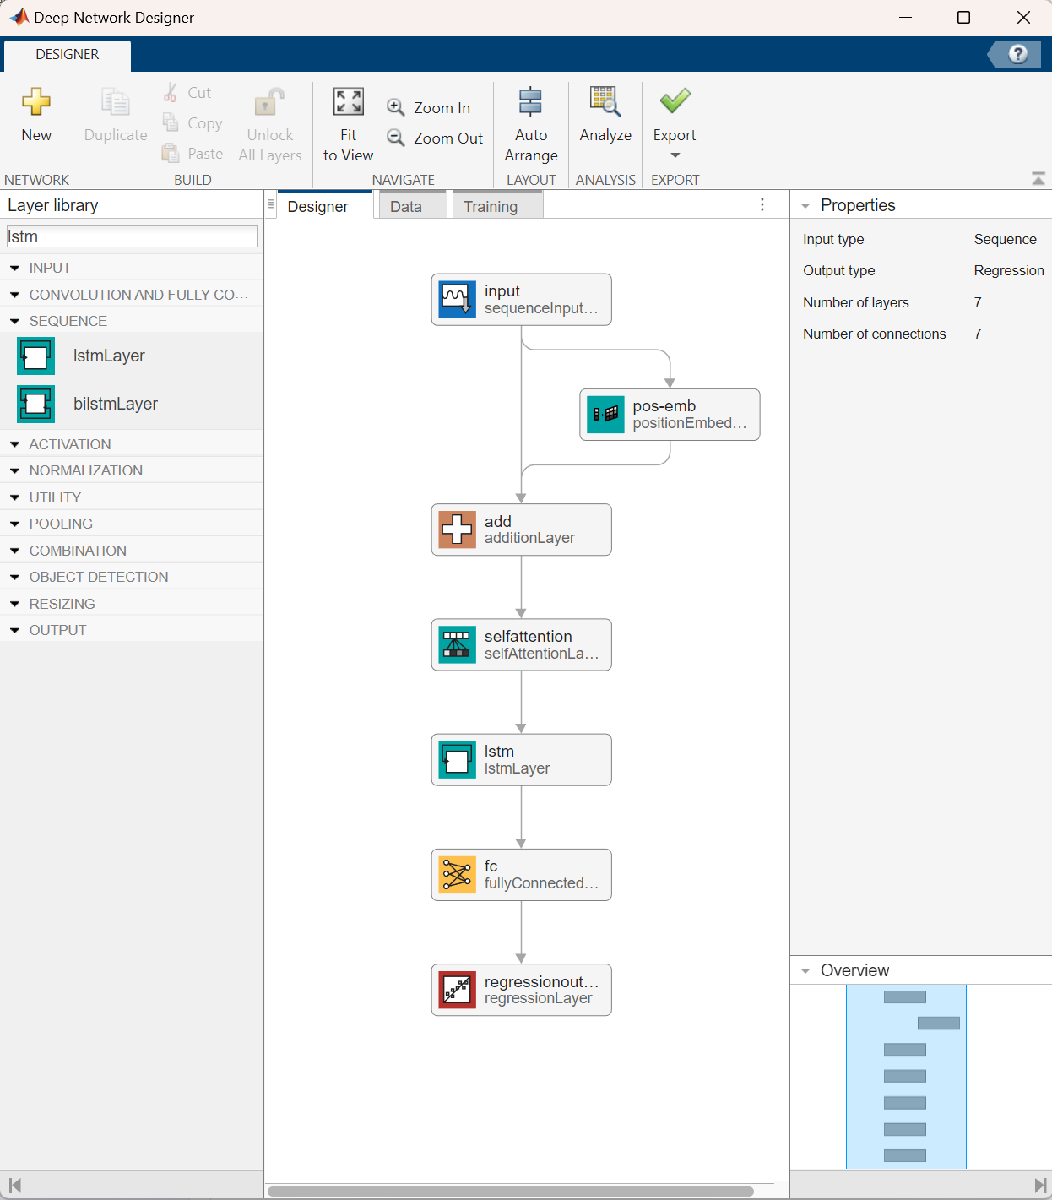

#### Multihead Self-Attention LSTM Network

lgraph = layerGraph();
tempLayers = sequenceInputLayer(3,"Name","sequenceinput");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = selfAttentionLayer(12,768,"Name","selfattention","AttentionMask","causal","DropoutProbability",0.001);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = selfAttentionLayer(12,768,"Name","selfattention_1","AttentionMask","causal","DropoutProbability",0.001);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = selfAttentionLayer(12,768,"Name","selfattention_2","AttentionMask","causal","DropoutProbability",0.001);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(3,"Name","addition")
    lstmLayer(128,"Name","lstm","OutputMode","last")
    fullyConnectedLayer(3,"Name","fc")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

lgraph = connectLayers(lgraph,"sequenceinput","selfattention");
lgraph = connectLayers(lgraph,"sequenceinput","selfattention_1");
lgraph = connectLayers(lgraph,"sequenceinput","selfattention_2");
lgraph = connectLayers(lgraph,"selfattention","addition/in1");
lgraph = connectLayers(lgraph,"selfattention_1","addition/in2");
lgraph = connectLayers(lgraph,"selfattention_2","addition/in3");

#### 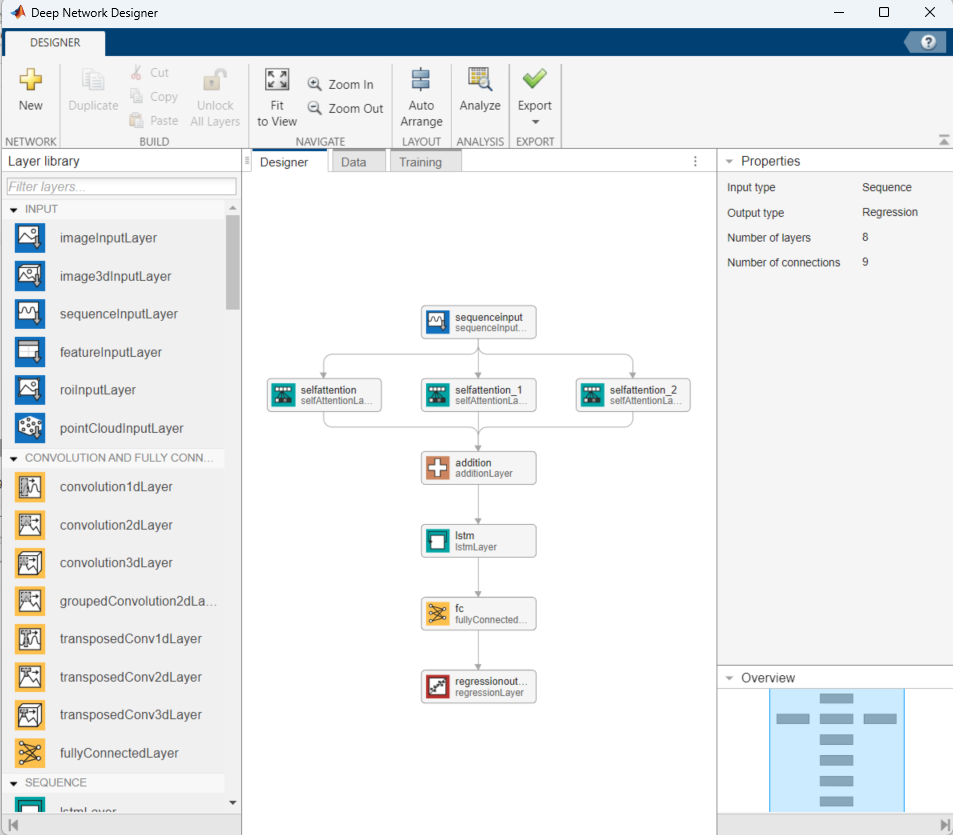

#### LSTM Network

nFeatures = 3;
layers = [
    sequenceInputLayer(nFeatures)
    lstmLayer(128, 'OutputMode', 'last')
    fullyConnectedLayer(nFeatures)
    regressionLayer];

#### 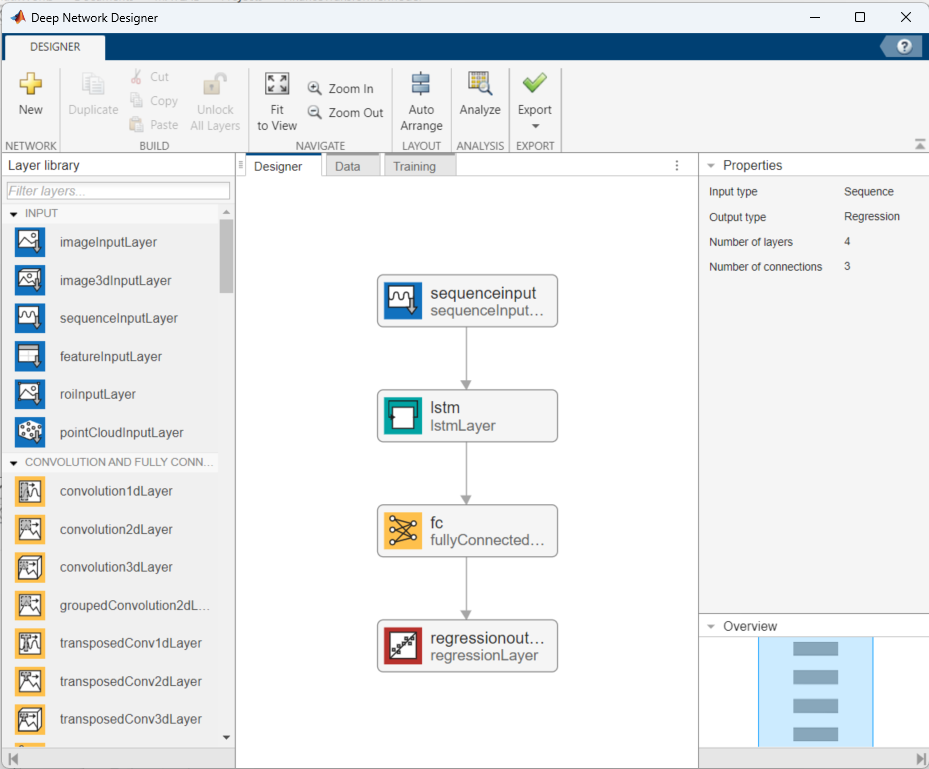

#### BiLSTM Network

nFeatures = 3;
layers = [
    sequenceInputLayer(nFeatures)
    bilstmLayer(128, 'OutputMode', 'last')
    fullyConnectedLayer(nFeatures)
    regressionLayer];

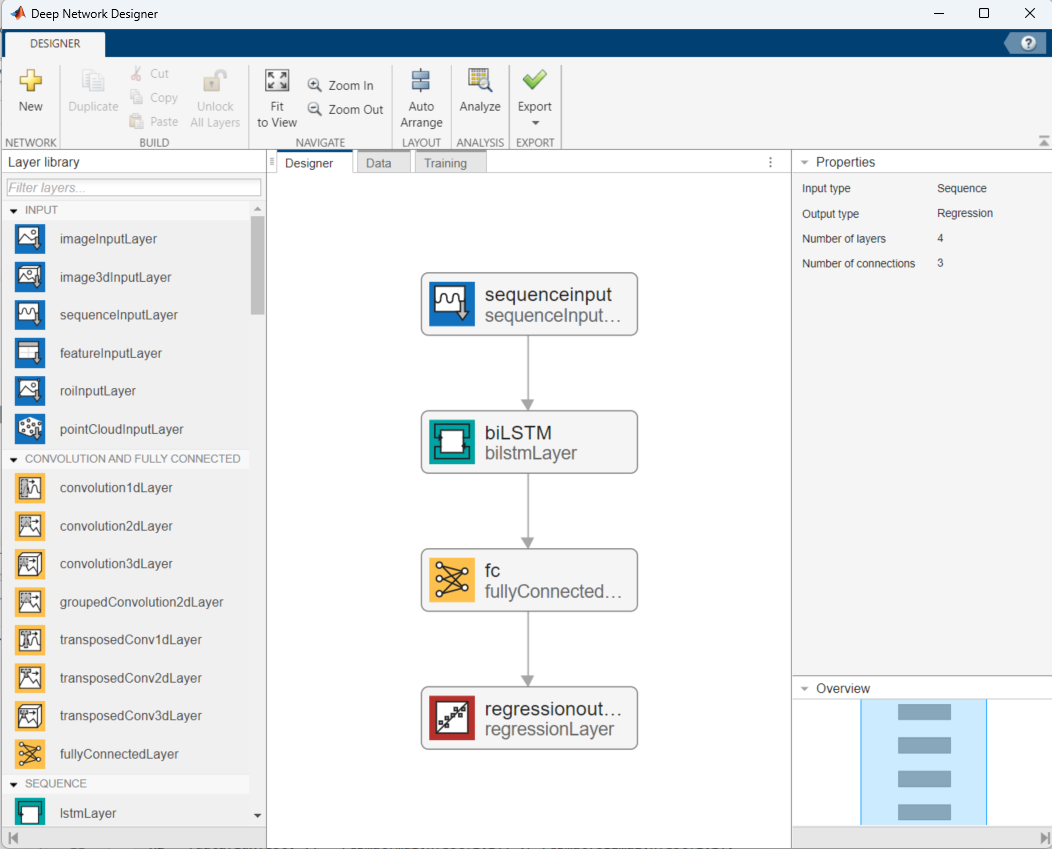

Copyright 2024 The MathWorks, Inc.